# SPH_2016_code

% Recreating algorithms and code from Singh, Perry, and Herter (2016) paper
% on computing ocular kinematics and classifying gaze events with KINARM
% end point

## Load sample data

clear; clc
cd('/Users/duncan/OneDrive - University of Delaware - o365/Documents/Presentations/Singh, Perry, Herter 2016/Sample_data')
data = zip_load;

Loading 570519758_2019-10-09_14-07-10.zip
......................... 
Finished loading all exam files.


cd('/Users/duncan/OneDrive - University of Delaware - o365/Documents/Presentations/Singh, Perry, Herter 2016')

## Pre-processing

Remove blinks and gaze artifacts

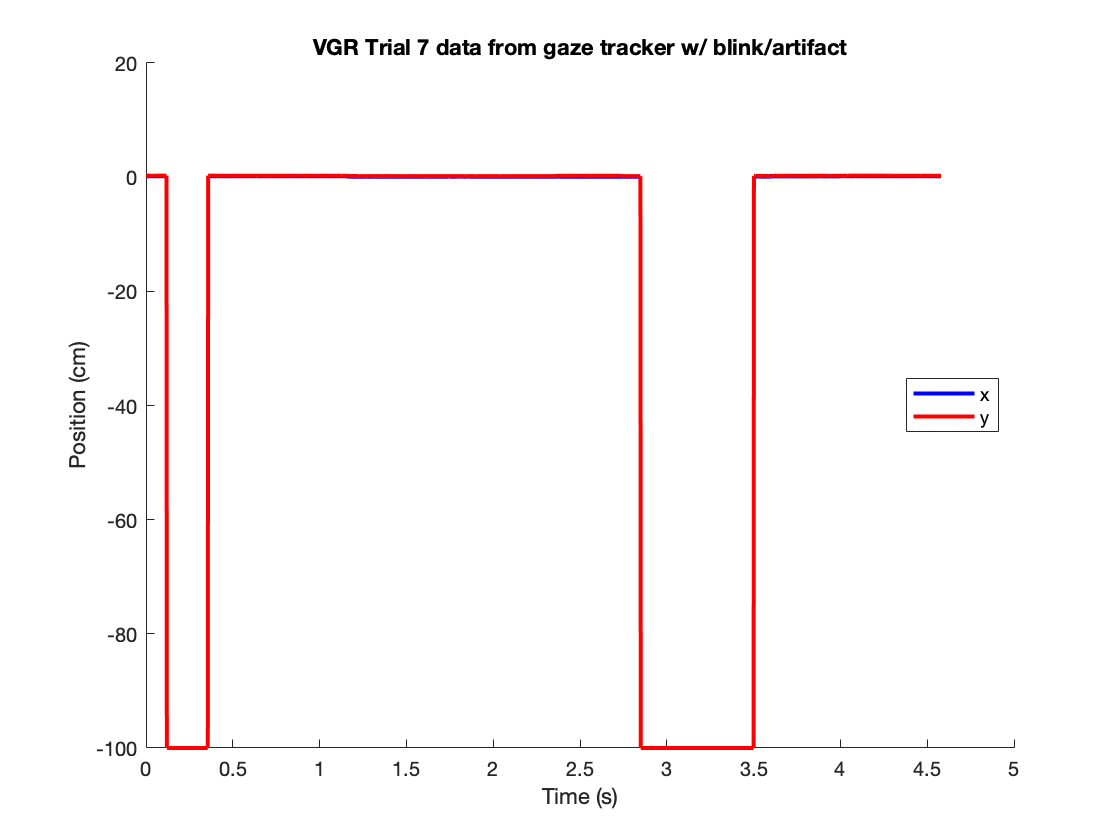

% Example: find and plot a trial with blink/gaze artifact

blinkx = data.c3d(7).Gaze_X;
blinky = data.c3d(7).Gaze_Y;
time = data.c3d(7).Gaze_TimeStamp(:) - data.c3d(7).Gaze_TimeStamp(1);

figure;
plot(time, blinkx, 'b-', 'linewidth', 2)
hold on 
plot(time, blinky, 'r-', 'linewidth', 2)
ylabel('Position (cm)')
xlabel('Time (s)')
title('VGR Trial 7 data from gaze tracker w/ blink/artifact')
legend('x', 'y', 'location', 'best')
box off 

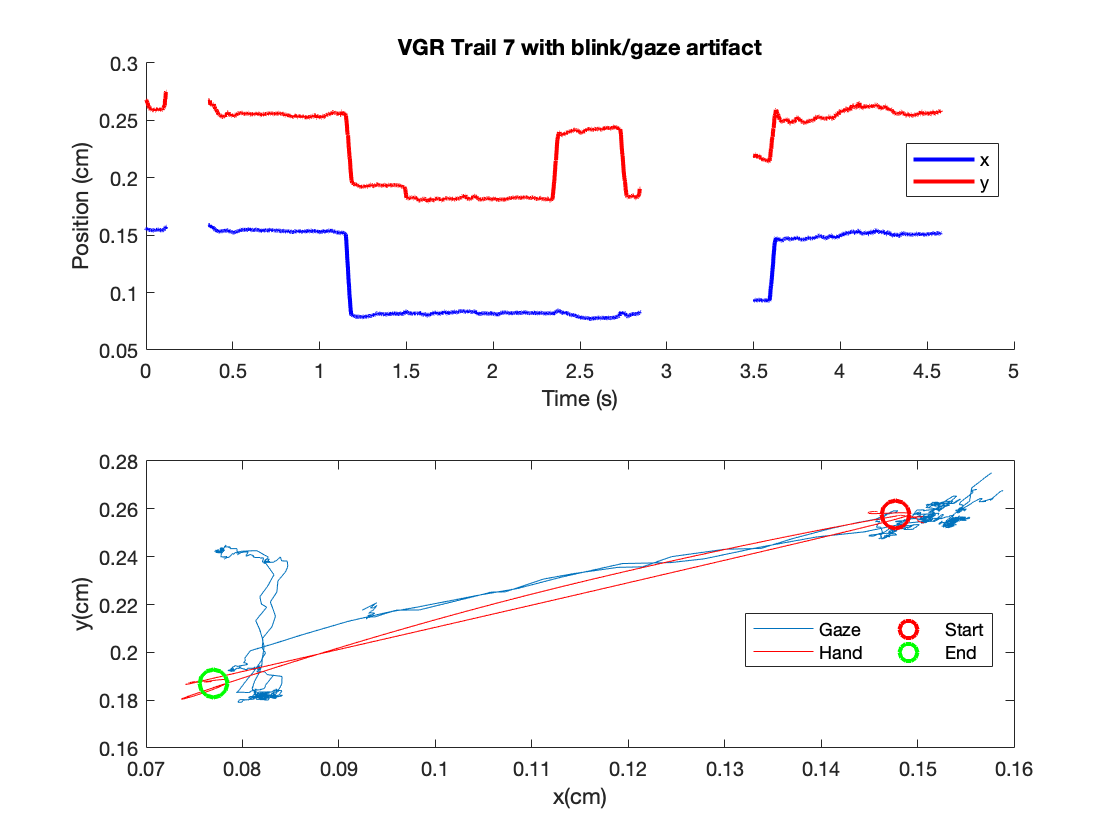

% saveas(gcf, 'tracker_raw.jpg')
% Replace -100 with nan to see underlying data 
for i = 1:length(blinkx)
    if blinkx(i) == -100
        blinkx(i) = nan;
        blinky(i) = nan;
    end
end
figure;
subplot(2,1,1); plot(time,blinkx, 'b-', 'linewidth', 2)
hold on 
subplot(2,1,1); plot(time,blinky, 'r-', 'linewidth', 2)
box off
xlabel('Time (s)')
ylabel('Position (cm)')
legend('x', 'y', 'location', 'best')
title('VGR Trail 7 with blink/gaze artifact')
subplot(2,1,2); plot(blinkx, blinky)
hold on 
subplot(2,1,2); plot(data(1).c3d(7).Right_HandX,data(1).c3d(7).Right_HandY, 'r')
target1 = [data(1).c3d(7).TARGET_TABLE.X_GLOBAL(1), data(1).c3d(7).TARGET_TABLE.Y_GLOBAL(1)];
target2 = [data(1).c3d(7).TARGET_TABLE.X_GLOBAL(7), data(1).c3d(7).TARGET_TABLE.Y_GLOBAL(7)];
subplot(2,1,2); plot(target1(1)/100, target1(2)/100, 'ro', 'markersize', 14, 'linewidth', 2)
subplot(2,1,2); plot(target2(1)/100, target2(2)/100, 'go', 'markersize', 14, 'linewidth', 2)
legend('Gaze', 'Hand', 'Start', 'End', 'NumColumns', 2, 'location', 'best')
xlabel('x(cm)')
ylabel('y(cm)')

% saveas(gcf, 'rawnan.jpg')
% Add missing data via cubic spline interpolation between last five and
% first five points 
[splinedx, splinedy] = blink_art(blinkx,blinky);

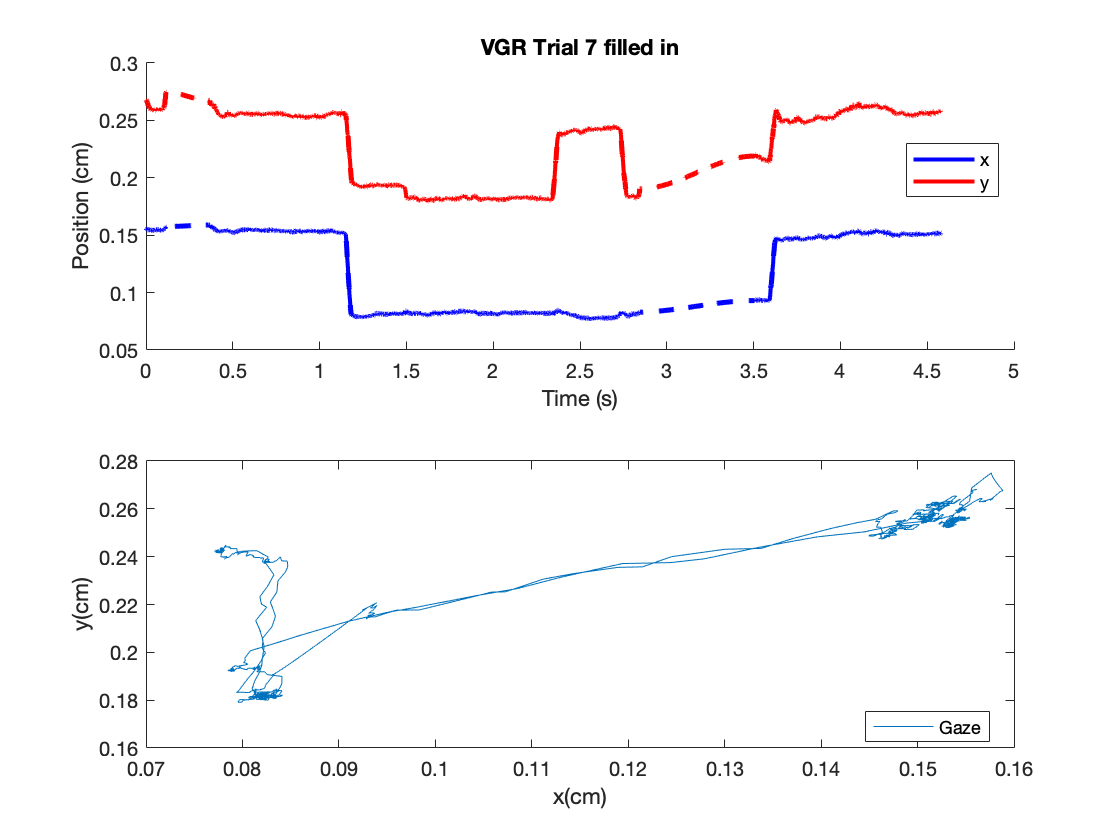

figure;
subplot(2,1,1); plot(time,blinkx, 'b-', 'linewidth', 2)
hold on 
subplot(2,1,1); plot(time,blinky, 'r-', 'linewidth', 2)
xlabel('Time (s)')
ylabel('Position (cm)')
box off
plot(time,splinedx, 'b--', 'linewidth', 2)
plot(time,splinedy, 'r--', 'linewidth', 2)
title('VGR Trial 7 filled in')
legend('x', 'y', 'location', 'best')
subplot(2,1,2); plot(splinedx,splinedy)
xlabel('x(cm)')
ylabel('y(cm)')
legend('Gaze', 'location', 'best')

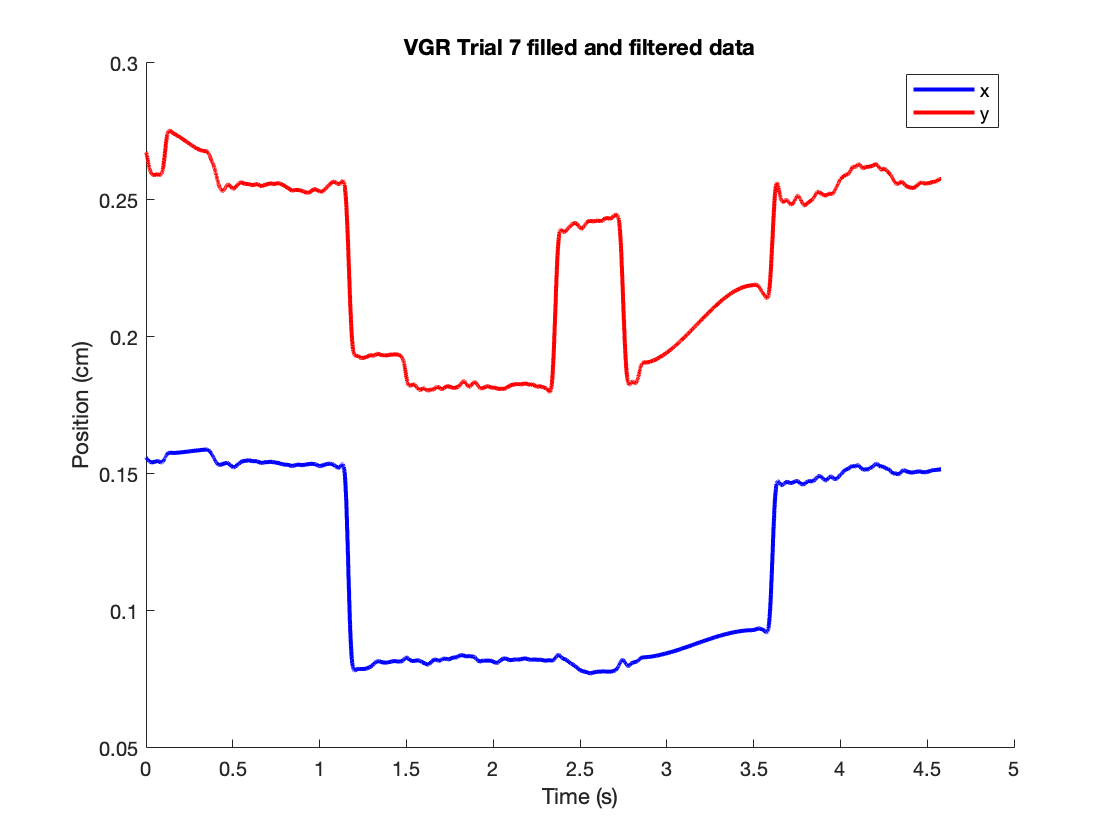

% saveas(gcf, 'csi.jpg')
% 2nd order low-pass Butterworth filter @ 20 Hz
[b,a] = butter(2,20/500); 
filtx = filtfilt(b,a,splinedx);
filty = filtfilt(b,a,splinedy);

figure;
plot(time, filtx, 'b-', 'linewidth', 2)
hold on 
plot(time, filty, 'r-', 'linewidth', 2)
title('VGR Trial 7 filled and filtered data')
xlabel('Time (s)')
ylabel('Position (cm)')
box off
legend('x', 'y', 'location', 'best')

% saveas(gcf, 'csi_filt.jpg')


## Transformation # 1

% Transform from 2D Cartesian to eye-based 3D spherical CS 

h = 333; % height of eye from stimulus plane (from Dr.Singh code (in mm))
heightv = [0;0;h];
prime = zeros([3 size(filtx,1)]);
sphere = zeros([3 size(filtx,1)]);
for i = 1:length(filtx)  
    
    % position vector 
    posv = [filtx(i); filty(i); 0];
    
    % rotation matrix 
    R = eye(3); % from Dr. Singh code

    % Equation 2
    prime(:,i) = heightv + R*posv; % equation 2
    
    % Equations 3a - 3c
    sphere(1,i) = sqrt(prime(1,i)^2 + prime(2,i)^2 + prime(3,i)^2); % rho
    sphere(2,i) = atan(prime(2,i)/prime(1,i)); % theta (in radians)
    sphere(3,i) = acos(prime(3,i)/sphere(1,i)); % phi (in radians)
end


## Transformation #2 

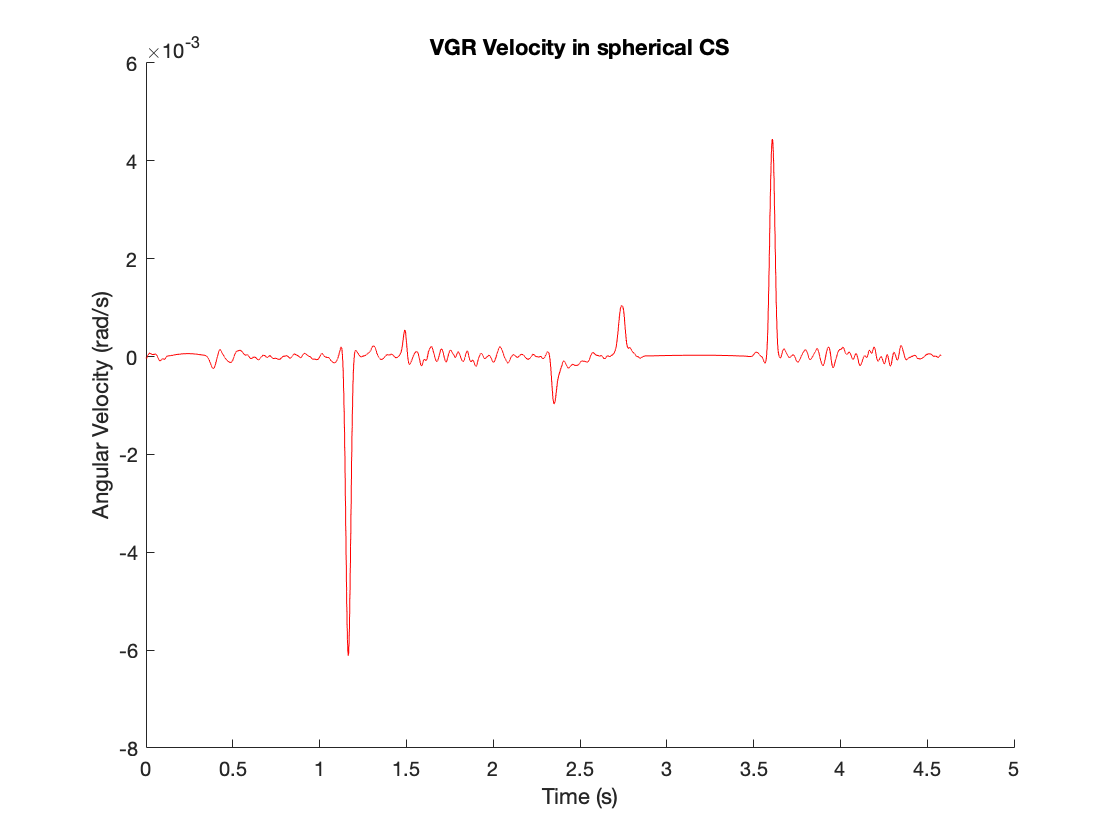

% Transform from eye based Cartesian to eye based spherical CS

% pre calculations 
% no filter 
xprime_dot_nf = derivative(prime(1,:)) ./ derivative(time');
yprime_dot_nf = derivative(prime(2,:)) ./ derivative(time');
zprime_dot_nf = 0; % (from Dr. Singh code)

% add Savitzky-Golay filtering (from Dr. Singh code) [useable parameters?]
xprime_dot = sgolayfilt(xprime_dot_nf,8,41);
yprime_dot = sgolayfilt(yprime_dot_nf,8,41);
zprime_dot = 0;

% 4a & 4b
% convert from cartesian to spherical CS
[theta,phi,rho] = cart2sph(prime(1,:),prime(2,:),prime(3,:));

phi_dot = zeros([length(xprime_dot) 1]);
theta_dot = zeros([length(xprime_dot) 1]);
rho_dot = zeros([length(xprime_dot) 1]);
for i = 1:length(xprime_dot)
    
    % phi 
    phi_n = prime(3,i)*((prime(1,i)*xprime_dot(i)) + (prime(2,i)*yprime_dot(i))) ...
        - (((prime(1,i)^2 + prime(2,i)^2))*zprime_dot); 
    phi_d = (prime(1,i)^2 + prime(2,i)^2 + prime(3,i)^2)*sqrt(prime(1,i)^2 + prime(2,i)^2);
    phi_dot(i) =  phi_n / phi_d;
    
    % theta 
    theta_n = (prime(2,i)*xprime_dot(i)) - (prime(1,i)*yprime_dot(i));
    theta_d = (prime(1,i)^2 + prime(2,i)^2); 
    theta_dot(i) =  (theta_n / theta_d); % took out "* cos(phi(i))" from Dr. Singh code
    
    % rho (from Dr. Singh code)
    rho_n = ((prime(1,i)*xprime_dot(i))+(prime(2,i)*yprime_dot(i))+(prime(3,i)*zprime_dot));
    rho_d = rho(i);
    rho_dot(i) =  rho_n / rho_d;
   
end

% Equation 5: velocity vector in spherical coordinates

% create unit vectors 
sphere_u = zeros([3 length(sphere)]);
for i = 1:length(sphere)
    sphere_u(:,i) = makeU(sphere(:,i));
end
v = zeros([3 length(phi_dot)]);
for i = 1:length(phi_dot)
    v(:,i) = (rho_dot(i)*sphere_u(1,i)) + ...
        (sphere(1,i)*theta_dot(i)*sin(sphere(3,i)*sphere_u(2,i))) + ...
        (sphere(1,i)*phi_dot(i)*sphere_u(3,i));
end

% plot velocities (each axis shows same pattern)
figure;
plot(time, v(1,:), 'r-')
hold on 
% plot(time, v(2,:), 'b-')
% plot(time, v(3,:), 'm-')
xlabel('Time (s)')
ylabel('Angular Velocity (rad/s)')
title('VGR Velocity in spherical CS')
box off 

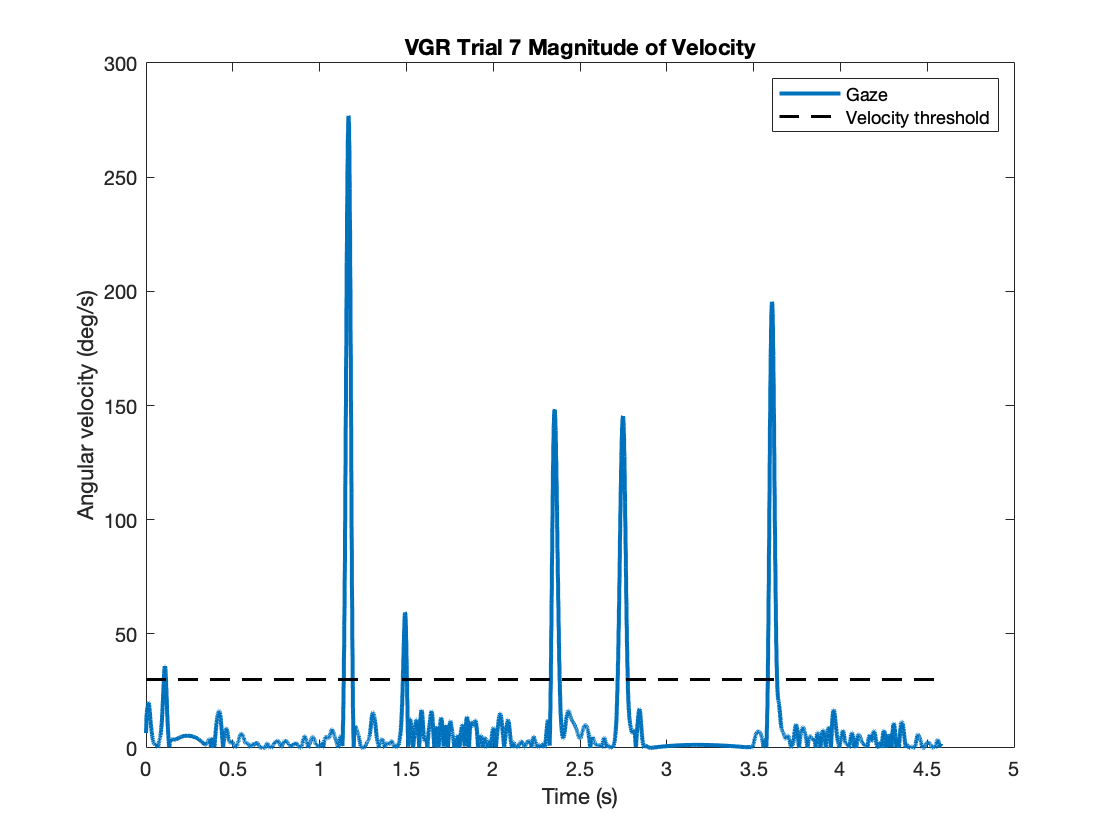

% saveas(gcf,'vel_sphere.jpg')
% Equation 5 (as in Dr. Singh code)
gazevel = (bsxfun(@hypot, theta_dot, phi_dot)*(180/pi));
figure;
plot(time, gazevel, 'linewidth', 2)
xlabel('Time (s)')
ylabel('Angular velocity (deg/s)')
title('VGR Trial 7 Magnitude of Velocity')
hold on 
line([0 time(end)], [30 30], 'linestyle', '--', 'color', 'k', 'linewidth', 1.5)
legend('Gaze', 'Velocity threshold')

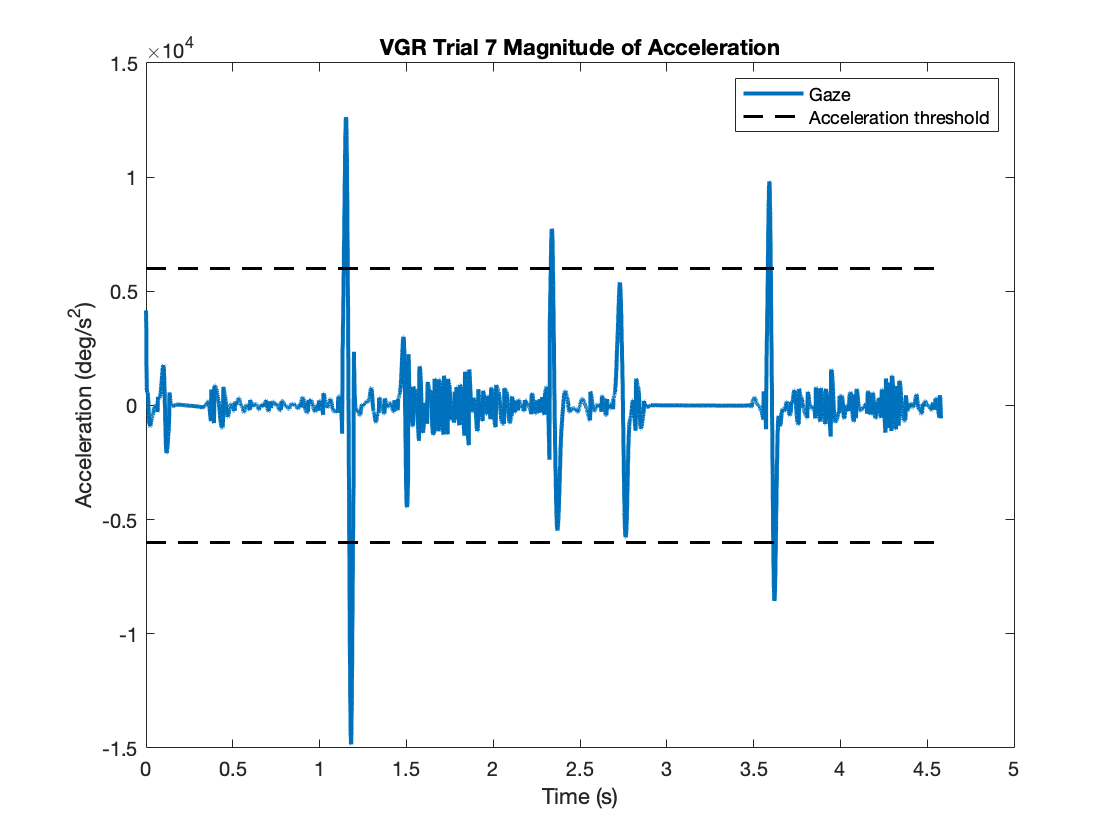

% saveas(gcf, 'mag_vel.jpg')
% acceleration (as in Dr. Singh code) 
gazeacc = derivative(gazevel)*1e3;
figure;
plot(time, gazeacc, 'linewidth', 2)
hold on 
line([0 time(end)], [6000 6000], 'color', 'k', 'linewidth', 1.5, 'linestyle', '--')
line([0 time(end)], [-6000 -6000], 'color', 'k', 'linewidth', 1.5, 'linestyle', '--')
xlabel('Time (s)')
ylabel('Acceleration (deg/s^2)')
title('VGR Trial 7 Magnitude of Acceleration')
legend('Gaze', 'Acceleration threshold')

% saveas(gcf, 'mag_acc.jpg')


## Foveal visual radius

vis_ang = 3;
calibration_er = 0.5; 
delta = vis_ang + calibration_er; % degrees

FVR = rho(1) * tand(delta/2)*csc(asin(h/rho(1)));


## Compute velocity threshold 

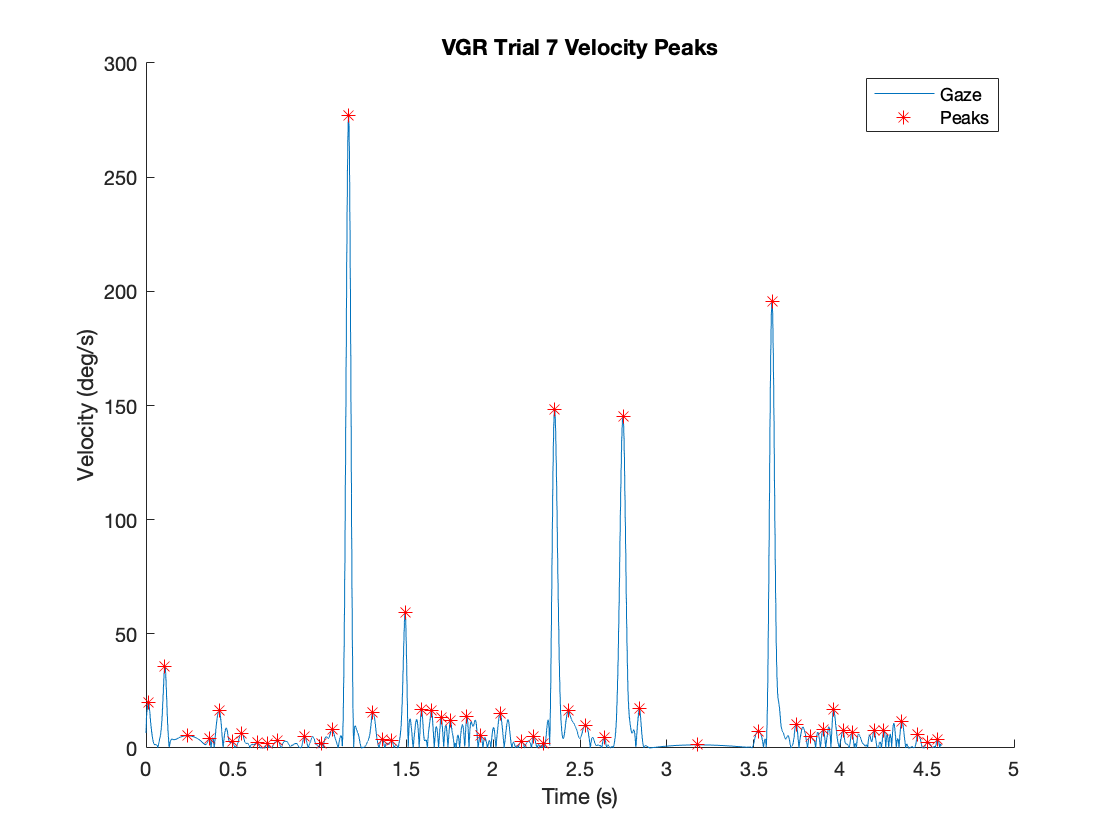

% Code adapted from Dr. Singh's
% IC's 
max_it_mle = 600;
max_fun_evals_mle = 800; 
pStart = 0.1;
muStart_range = [.15 .85];
bin_size = .2;

% find local peaks that satisfy 2 conditions
[peaks, locations] = findpeaks(gazevel, 'minpeakheight', 0.5, 'minpeakdistance', 50);

figure;
plot(time, gazevel)
hold on 
plot(locations/1000, peaks, 'r*')
xlabel('Time (s)')
ylabel('Velocity (deg/s)')
legend('Gaze', 'Peaks')
title('VGR Trial 7 Velocity Peaks')
box off 

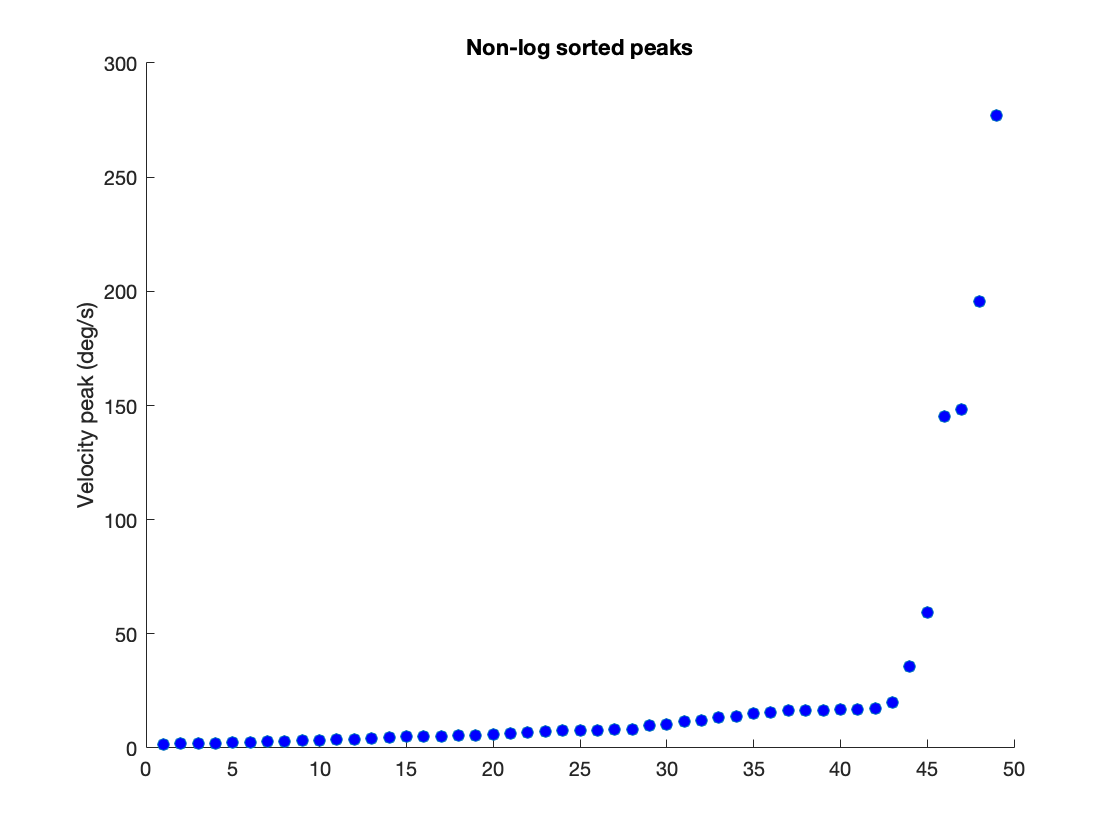

% saveas(gcf, 'vel_peaks.jpg')
% sort and then log transform peaks 
srtd = sort(peaks);
lgsrtpeaks = log(srtd);
x = lgsrtpeaks;
% get length for later 
vecleng = length(gazevel);

% non-log sorted peaks 
figure;
plot(srtd, 'o', 'markerfacecolor', 'b')
ylabel('Velocity peak (deg/s)')
title('Non-log sorted peaks')
box off

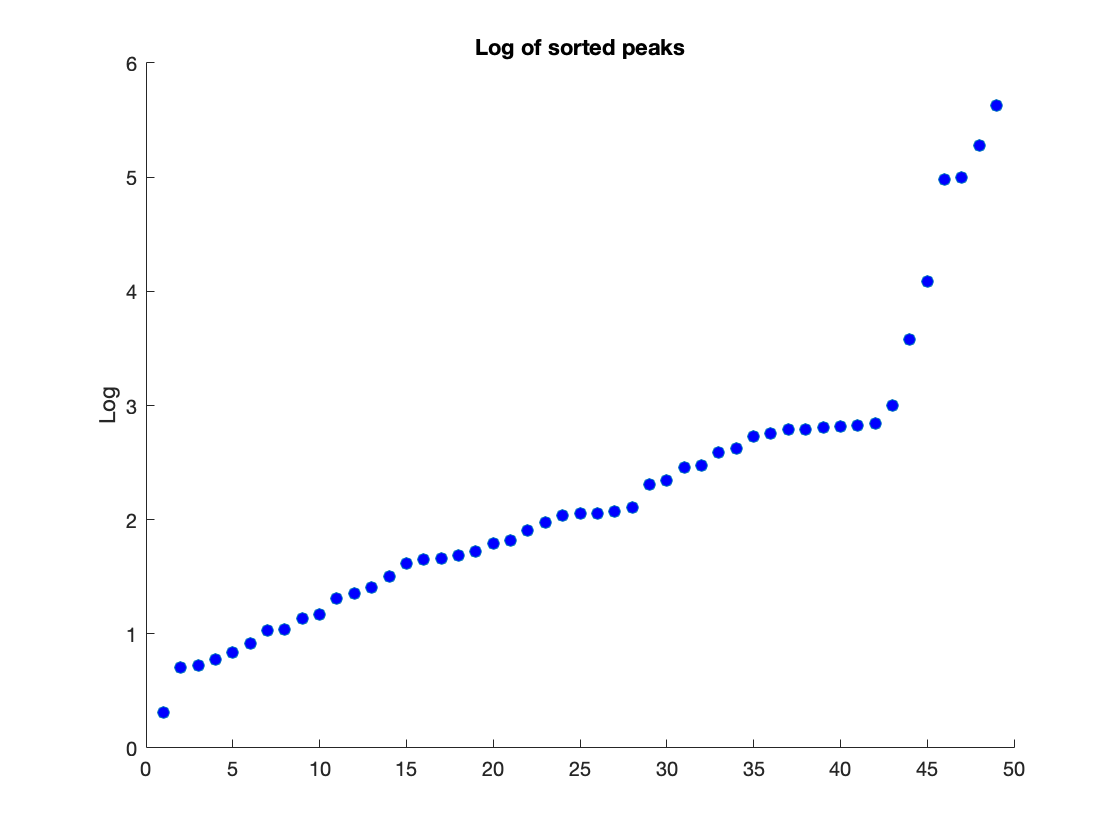

% saveas(gcf, 'nonlog.jpg')

% log sorted peak 
figure;
plot(lgsrtpeaks, 'o', 'markerfacecolor', 'b')
ylabel('Log')
box off
title('Log of sorted peaks')

% saveas(gcf, 'logsortpeaks.jpg')

% combine two probabilty density functions 
pdf_normmix = @(x,p,mu1,mu2,sigma1,sigma2) p*normpdf(x,mu1,sigma1) + (1-p)*normpdf(x,mu2,sigma2);
% initial guess of parameters 
muStart = quantile(x, muStart_range);
sigmaStart = sqrt(var(x) - .25*diff(muStart).^2);
start = [pStart muStart sigmaStart sigmaStart];
lb = [0 -Inf -Inf 0 0];
ub = [1 Inf Inf Inf Inf];

options = statset('MaxIter', max_it_mle, 'MaxFunEvals', max_fun_evals_mle);
paramEsts = mle(x, 'pdf', pdf_normmix, 'start', start, 'lower', lb, 'upper', ub, 'options', options);

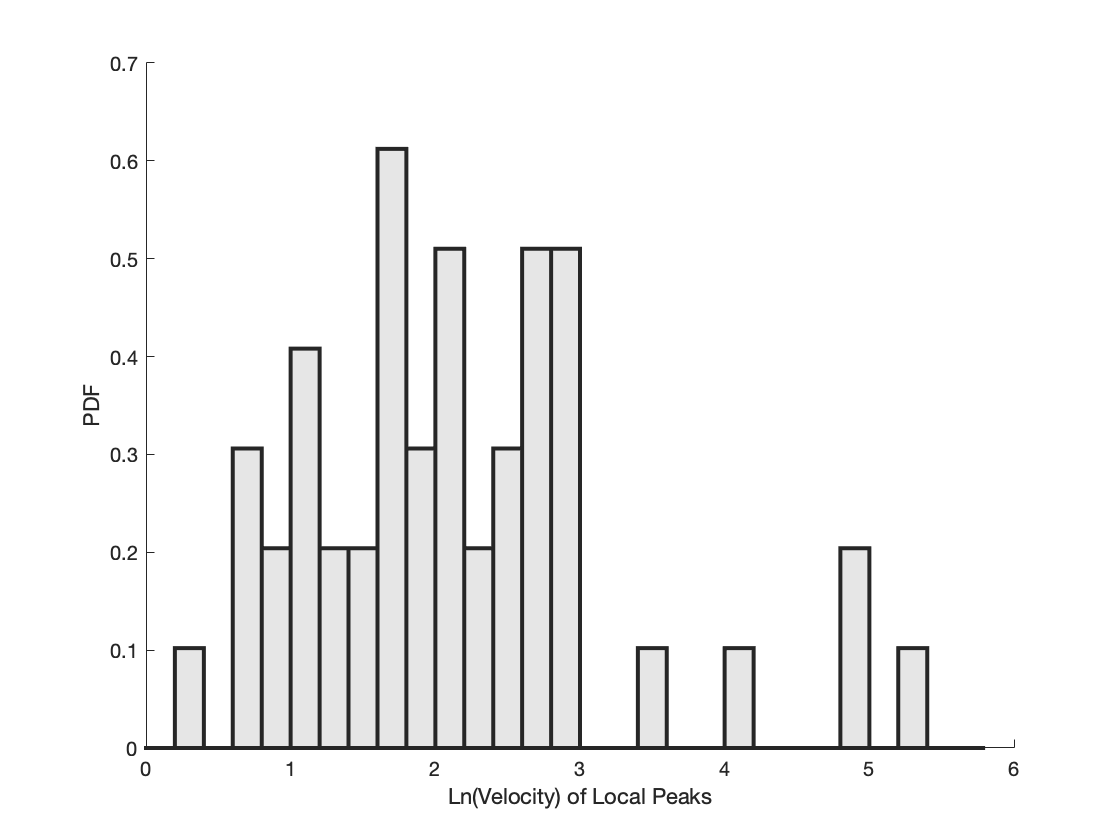

% plot lognormal distrubtion (no fit)
bins = 0:bin_size:max(x);
figure;
h = bar(bins, histc(x,bins)/(length(x)*bin_size),'histc');
set(h,'facecolor',[.9 .9 .9],'linewidth', 2);
box off 
ylabel('PDF')
xlabel('Ln(Velocity) of Local Peaks')

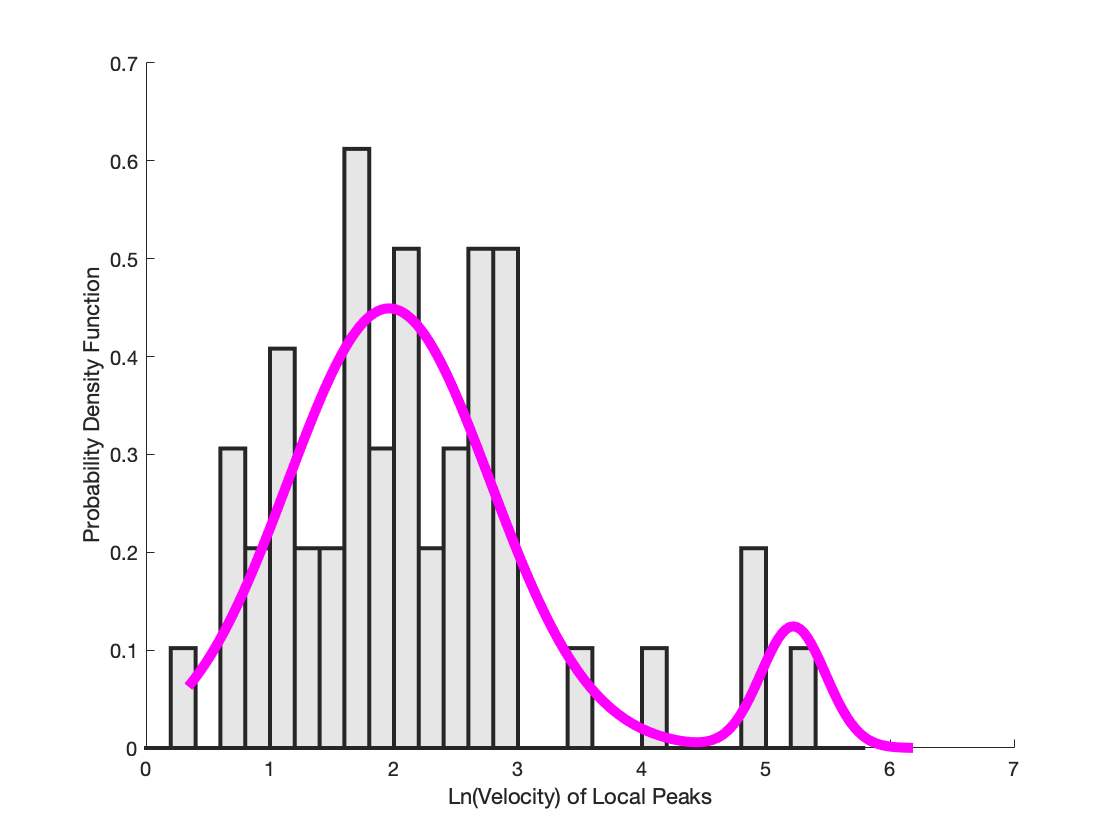

% saveas(gcf, 'ln_nofit.jpg')

% plot bimodal lognormal distribution 
figure;
h = bar(bins, histc(x,bins)/(length(x)*bin_size),'histc');
set(h,'facecolor',[.9 .9 .9],'linewidth', 2);
xgrid = linspace(1.1*min(x),1.1*max(x),200);
pdfgrid = pdf_normmix(xgrid, paramEsts(1),paramEsts(2),paramEsts(3),paramEsts(4),paramEsts(5));
hold on 
plot(xgrid,pdfgrid, 'linewidth', 5, 'linestyle', '-', 'color', 'm');
hold off 
xlabel('Ln(Velocity) of Local Peaks')
ylabel('Probability Density Function')
box off 

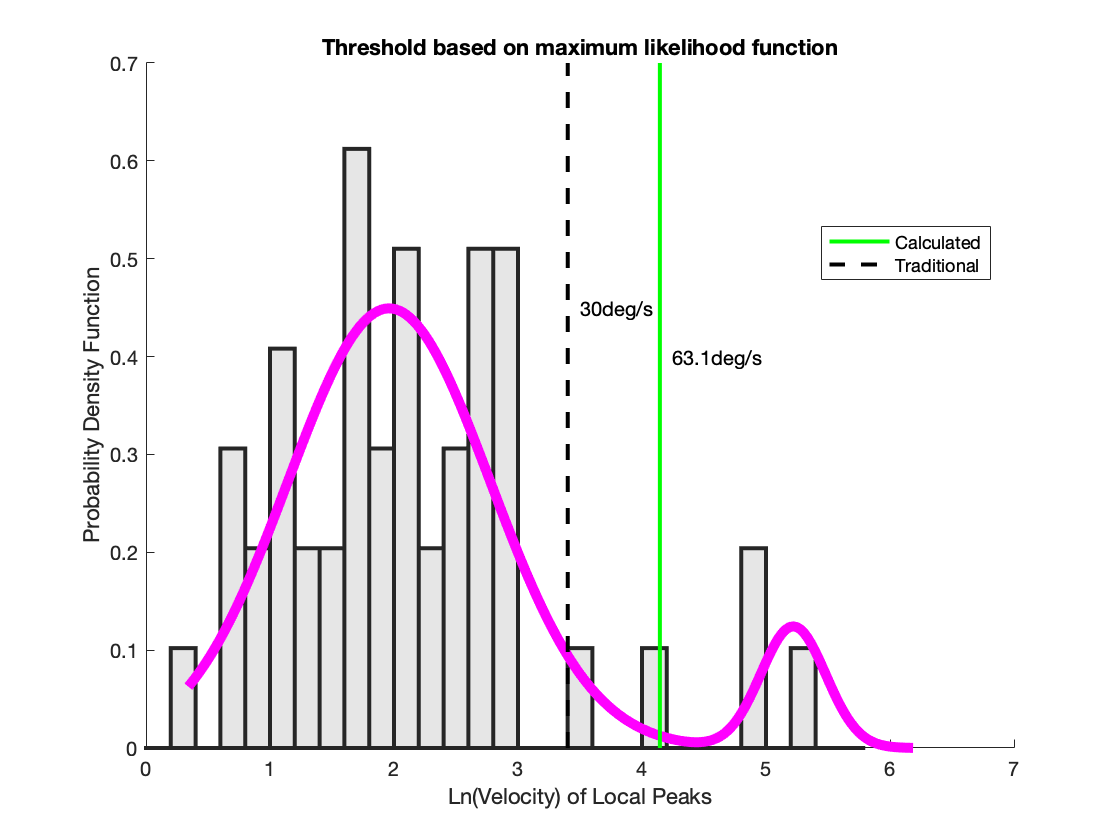

% saveas(gcf, 'fitbimod.jpg')
% plot with new thresholds 
figure;
h = bar(bins, histc(x,bins)/(length(x)*bin_size),'histc');
set(h,'facecolor',[.9 .9 .9],'linewidth', 2);
xgrid = linspace(1.1*min(x),1.1*max(x),200);
pdfgrid = pdf_normmix(xgrid, paramEsts(1),paramEsts(2),paramEsts(3),paramEsts(4),paramEsts(5));
hold on 
plot(xgrid,pdfgrid, 'linewidth', 5, 'linestyle', '-', 'color', 'm');
hold off 
xlabel('Ln(Velocity) of Local Peaks')
ylabel('Probability Density Function')
box off 
hold on 
% new calculations 
lower_saccade_vel = paramEsts(3) - (2*paramEsts(5));
upper_fixation_vel = paramEsts(2) + (2*paramEsts(4));
vel_threshold = exp(0.5*((lower_saccade_vel)+(upper_fixation_vel)));
l1 = line([log(vel_threshold) log(vel_threshold)], [0 .7], 'color', 'g', 'linewidth', 2);
text(log(vel_threshold)+0.1, 0.4, sprintf('%.1fdeg/s', vel_threshold))
trad = log(30);
l2 = line([trad trad], [0 0.7], 'color', 'k', 'linewidth', 2, 'linestyle', '--');
text(trad+0.1, 0.45, '30deg/s')
title('Threshold based on maximum likelihood function')
legend([l1 l2], {'Calculated', 'Traditional'}, 'location', 'best')

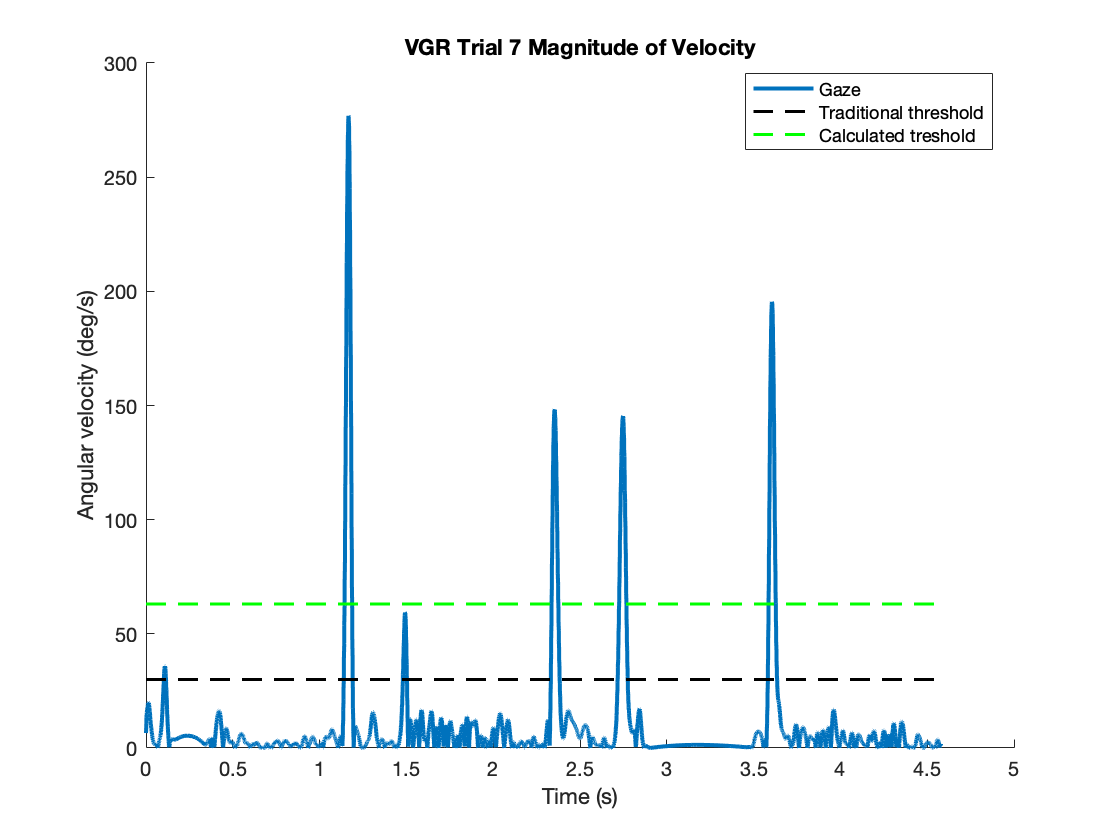

% saveas(gcf, 'newthres.jpg')
% Replot velocities with new threshold 
figure;
plot(time, gazevel, 'linewidth', 2);
xlabel('Time (s)')
ylabel('Angular velocity (deg/s)')
title('VGR Trial 7 Magnitude of Velocity')
hold on 
line([0 time(end)], [30 30], 'linestyle', '--', 'color', 'k', 'linewidth', 1.5);
line([0 time(end)], [vel_threshold vel_threshold], 'linestyle', '--', 'color', 'g', 'linewidth', 1.5)
legend('Gaze', 'Traditional threshold', 'Calculated treshold', 'location', 'best')
box off

% saveas(gcf, 'mag_vel_newthres.jpg')


## Classify events 

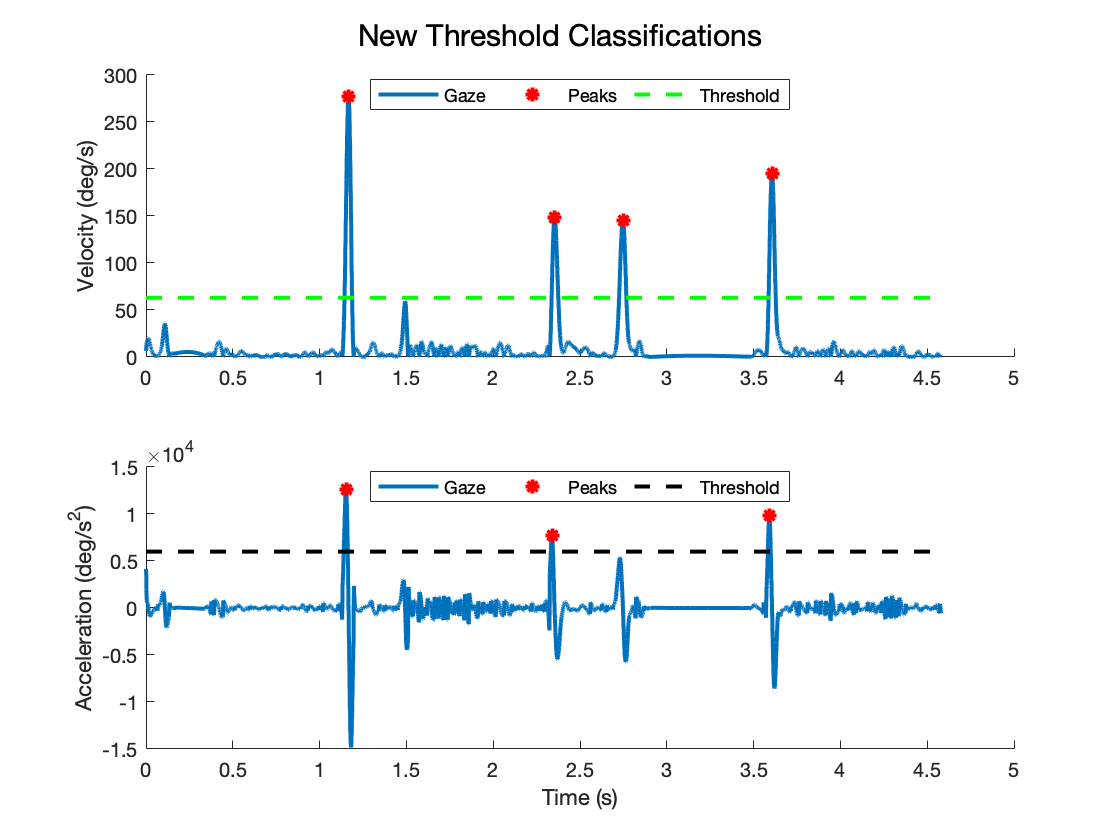

% Saccades 
% qualified velocities peaks 
[newvelpks,newvellocs] = findpeaks(gazevel, 'minpeakheight', vel_threshold, 'minpeakdistance', 5^2);
% qualified acceleration peaks 
[newaccpks,newacclocs] = findpeaks(gazeacc, 'minpeakheigh', 6000);

figure;
subplot(2,1,1); plot(time, gazevel, 'linewidth', 2)
hold on 
plot(newvellocs/1000, newvelpks, 'r*', 'linewidth', 2)
line([0 time(end)], [vel_threshold vel_threshold], 'color', 'g', 'linewidth', 2, 'linestyle', '--')
ylabel('Velocity (deg/s)')
box off
legend('Gaze', 'Peaks', 'Threshold', 'numcolumns', 3, 'location', 'best')
subplot(2,1,2); plot(time, gazeacc, 'linewidth', 2)
hold on 
plot(newacclocs/1000, newaccpks, 'r*', 'linewidth', 2)
line([0 time(end)], [6000 6000], 'color', 'k', 'linewidth', 2, 'linestyle', '--')
ylabel('Acceleration (deg/s^2)')
xlabel('Time (s)')
legend('Gaze', 'Peaks', 'Threshold', 'numcolumns', 3, 'location', 'best')
box off
sgtitle('New Threshold Classifications')

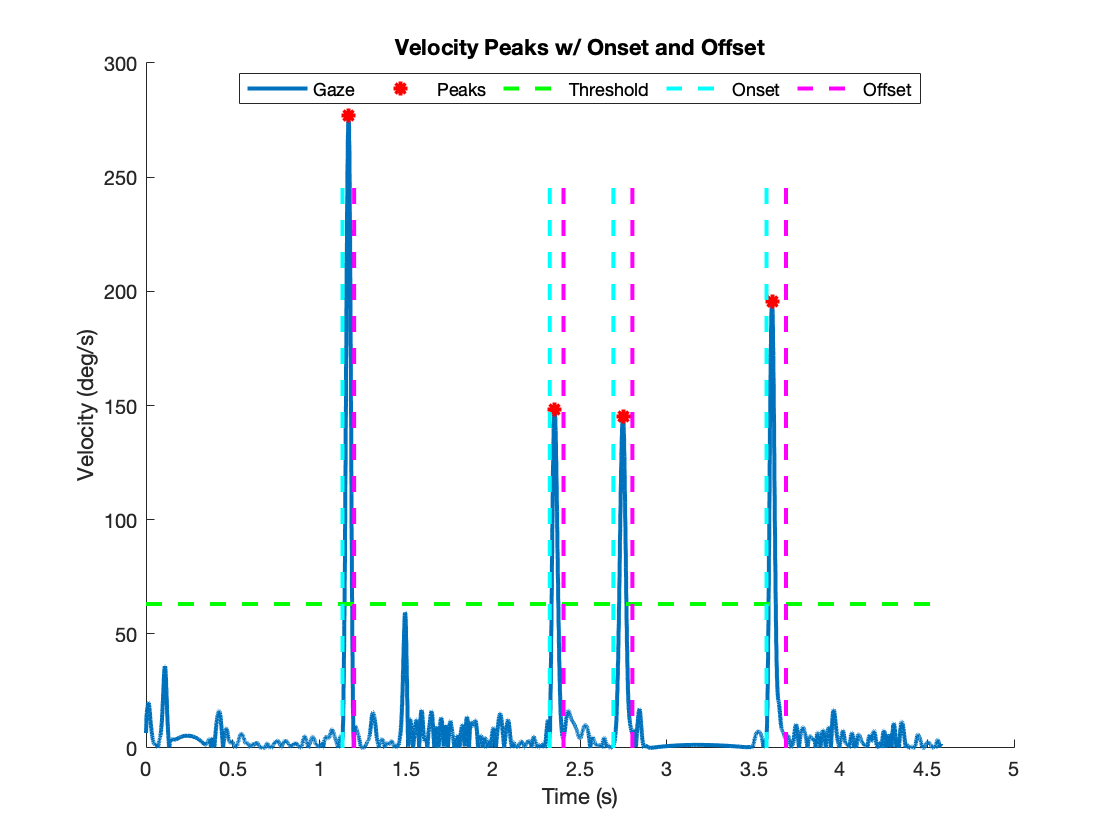

% exportgraphics(gcf,'saccade_class.jpg')
% Determine onset and offset (adapted from Dr. Singh code)
vellcs_plus = newvellocs + 120;
vellcs_minus = newvellocs - 120;
search = [vellcs_minus newvellocs vellcs_plus];
% search(1:3,1) = max(1,search(1:3,1));
% search(end-2:end,3) = min(length(gazevel),search(end-2:end,3));
gaze_event_vec = zeros(length(gazevel), 1);
gaze_event_vec(gaze_event_vec ==0 & gazeacc>=6000)=1; % make sure pass acceleration too

for i = 1:size(search,1)
    % find onset section of velocity data
    onset_sector = gazevel(search(i,1):search(i,2));
    acc_onset_sect = derivative(onset_sector);
    
    if ~isempty(find(acc_onset_sect<0,1,'last'))
        onset_vel(i) = onset_sector(find(acc_onset_sect<0,1,'last')+1);
        onset_loc = find(acc_onset_sect<0,1,'last')+search(i,1);
    else
        onset_vel(i) = 8; % 8 deg/s fair assumption (via Dr. Singh)
        onset_loc = search(i,1);
    end
    
    % find offeset section of velocity data 
    offset_sector = gazevel(search(i,2):search(i,3));
    acc_offset_sect = derivative(offset_sector);
    
    % not sure why the && statment 
    if ~isempty(find(acc_offset_sect>0,1,'first')) && (length(offset_sector)>=(find(acc_offset_sect>0,1,'first')+1)) 
        offset_vel(i) = offset_sector(find(acc_offset_sect>0,1,'first')+1);
        offset_loc = find(acc_offset_sect>0,1,'first')+search(i,2);
    else 
        offset_vel(i) = 9; % 9 deg/s fair assumption (via Dr. Singh)
        offset_loc = search(i,3);
    end
    
    gaze_event_vec(onset_loc:offset_loc) = 1;
    
end

% calculate average onset velocity and offset velocity 
avg_ons_vel = mean(onset_vel);
avg_off_vel = mean(offset_vel);
    
figure;
plot(time, gazevel, 'linewidth', 2)
hold on 
plot(newvellocs/1000, newvelpks, 'r*', 'linewidth', 2)
line([0 time(end)], [vel_threshold vel_threshold], 'color', 'g', 'linewidth', 2, 'linestyle', '--')
ylabel('Velocity (deg/s)')
xlabel('Time (s)')
box off
for i = 1:length(gaze_event_vec)
    if gaze_event_vec(i) == 1 && gaze_event_vec(i-1) == 0
        line([i/1000 i/1000], [0 250], 'color', 'c', 'linestyle', '--', 'linewidth', 2)
    elseif gaze_event_vec(i) == 1 && gaze_event_vec(i+1) == 0
        line([i/1000 i/1000], [0 250], 'color', 'm', 'linestyle', '--', 'linewidth', 2)
    end
end
legend('Gaze', 'Peaks', 'Threshold', 'Onset', 'Offset', 'numcolumns', 5, 'location', 'best')
title('Velocity Peaks w/ Onset and Offset')

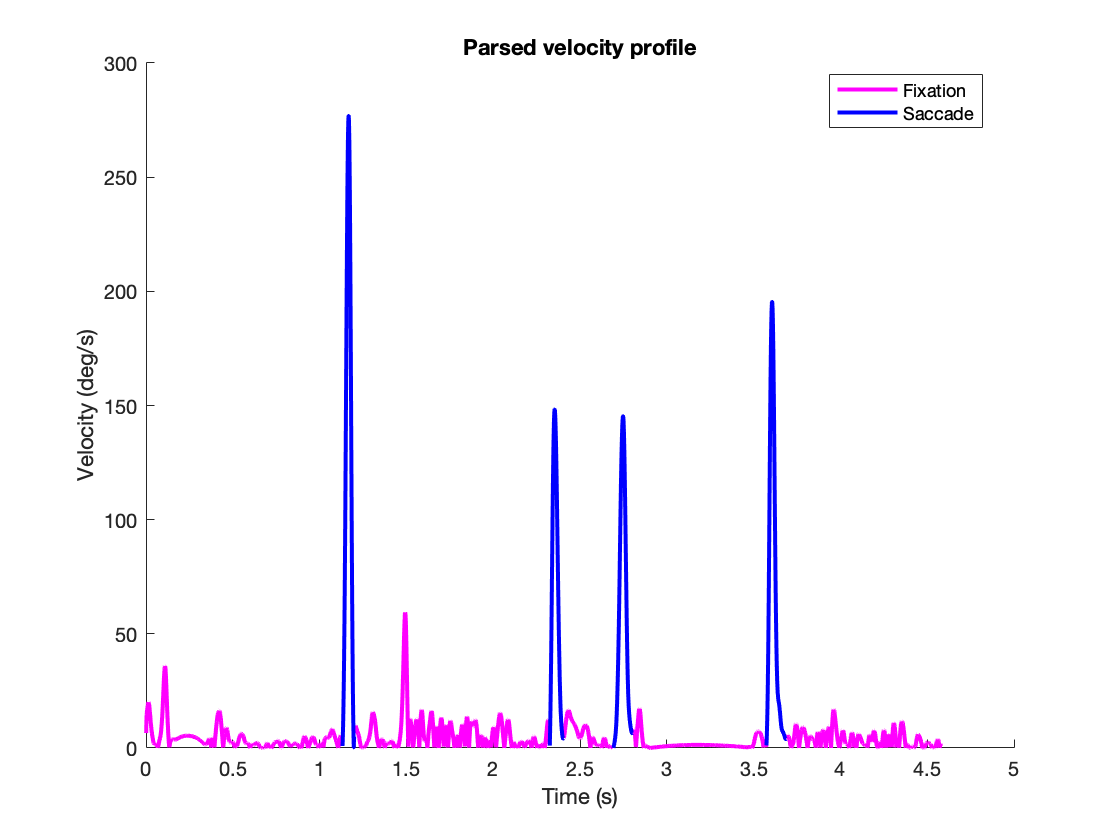

% saveas(gcf, 'vel_ons_off.jpg')
% Fixation 
% Must be below both velocity and acceleration thresholds 
% Must have a duration of at least 40 ms

% Easy fixation 
potent = zeros(length(gazevel),1);
for i = 1:length(gazevel)
    if gazevel(i) < vel_threshold && gazeacc(i) < 6000
        potent(i) = i;
    end
end

% Plot fixations and saccades together 
figure;
for i = 1:length(gazevel)
    if gaze_event_vec(i) == 1
        sac(i,1) = i;
        sac(i,2) = gazevel(i);
        
        fix(i,1:2) = nan;
    elseif potent(i) ~= 0
        fix(i,1) = i;
        fix(i,2) = gazevel(i);
        
        sac(i,1:2) = nan;
    end
end
p1 = plot(fix(:,1)/1000, fix(:,2), 'm-', 'linewidth', 2);
hold on 
p2 = plot(sac(:,1)/1000, sac(:,2), 'b-', 'linewidth', 2);
xlabel('Time (s)')
ylabel('Velocity (deg/s)')
box off 
title('Parsed velocity profile')
legend([p1 p2], {'Fixation', 'Saccade'}, 'location', 'best')

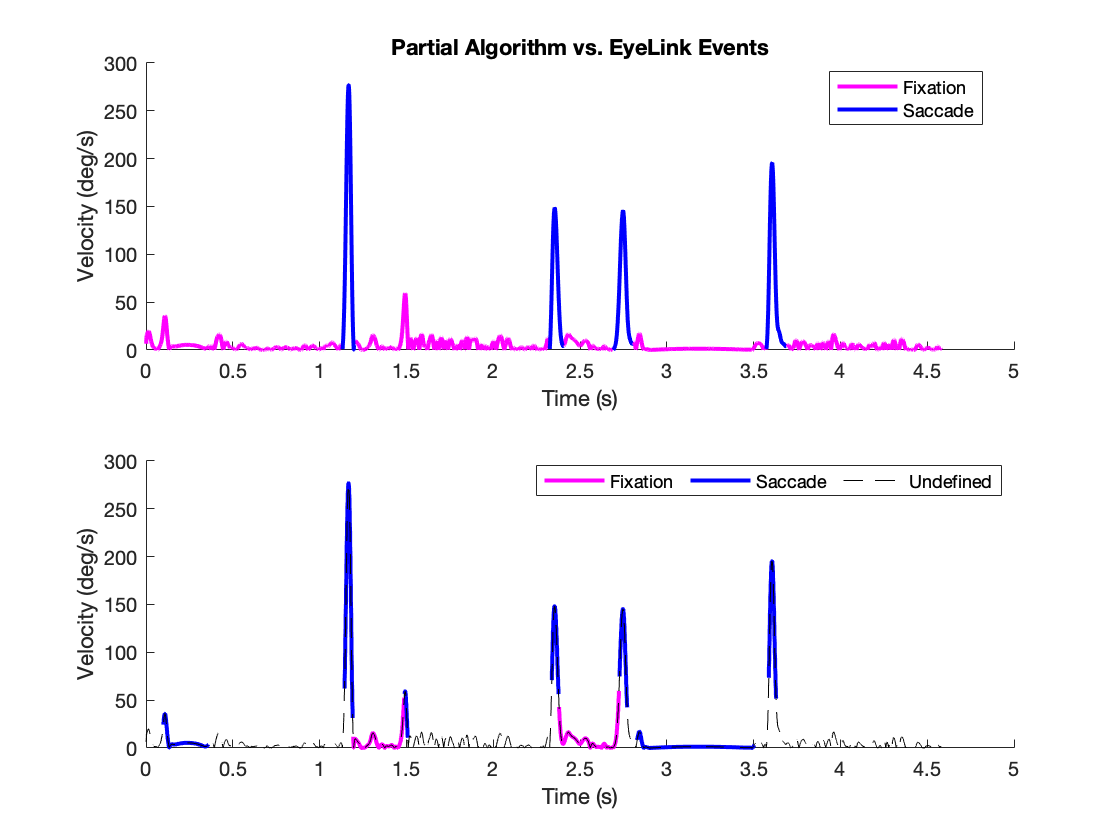

% saveas(gcf, 'parse_vel.jpg')

% Plot partial algorithm against EyeLink?
a = 1;
b = 1;
c = 1;
for i = 1:34
    if sum(i == [1,4,9,14,19,23,25,30]) == 1
        E_sacstart(a) = data(1).c3d(7).EVENTS.TIMES(i);
    elseif sum(i == [2,7,10,15,20,24,29,31]) == 1
        E_sacend(a) = data(1).c3d(7).EVENTS.TIMES(i);
        a = a + 1;
    elseif sum(i == [5,26]) == 1
        E_blstart(b) = data(1).c3d(7).EVENTS.TIMES(i);
    elseif sum(i == [6,28]) == 1
        E_blend(b) = data(1).c3d(7).EVENTS.TIMES(i);
        b = b+1;
    elseif sum(i == [11,21]) == 1
        E_fixstart(c) = data(1).c3d(7).EVENTS.TIMES(i);
    elseif sum(i == [13,22]) == 1
        E_fixend(c) = data(1).c3d(7).EVENTS.TIMES(i);
        c = c+1;
    end
end


figure;
subplot(2,1,1); p1 = plot(fix(:,1)/1000, fix(:,2), 'm-', 'linewidth', 2);
hold on 
p2 = plot(sac(:,1)/1000, sac(:,2), 'b-', 'linewidth', 2);
xlabel('Time (s)')
ylabel('Velocity (deg/s)')
box off 
title('Partial Algorithm vs. EyeLink Events')
legend([p1 p2], {'Fixation', 'Saccade'}, 'location', 'best')
subplot(2,1,2); 
for i = 1:length(E_fixend)
    fix = round(E_fixstart(i)*1000:1:E_fixend(i)*1000);
    p1 = plot(time(fix), gazevel(fix), 'm-', 'linewidth', 2);
    hold on 
end
for i = 2:length(E_sacend)
    sac = round(E_sacstart(i)*1000:1:E_sacend(i)*1000);
    p2 = plot(time(sac), gazevel(sac), 'b-', 'linewidth', 2);
    hold on 
end
box off 
p3 = plot(time,gazevel,'k--');
xlabel('Time (s)')
ylabel('Velocity (deg/s)')
legend([p1 p2 p3], {'Fixation', 'Saccade', 'Undefined'}, 'numcolumns', 3, 'location', 'best')

% saveas(gcf,'compare.jpg')


function [splinedx, splinedy] = blink_art(gazex,gazey)

% INPUTS: 
% gazex: vector of gaze data in x-dimension (-100 replaced w nan)
% gazey: vector of gaze data in y-dimension (-100 replaced w nan)

% outputs equal inputs (allow to replace certain sections 
splinedx = gazex;
splinedy = gazey;

% matrix of indicies for start and end of nan/missing sections
z = 0;
for i = 2:length(gazex)
    if isnan(gazex(i)) && ~isnan(gazex(i-1))
        idx = z+1;
        start_end(idx,1) = i;
        z = idx;
    elseif ~isnan(gazex(i)) && isnan(gazex(i-1))
        start_end(idx,2) = i-1;
        z = idx;
    end
end

% pull out data needed for spline function of respective sections 
% first 5 points before and after blink onset and termination 
for i = 1:size(start_end,1)
    pre_start = start_end(i,1)-5;
    post_end = start_end(i,2)+5;
    xgap = gazex(pre_start:post_end);
    ygap = gazey(pre_start:post_end);
    t = post_end - pre_start + 1;
    
    newx = spline(1:t,xgap,1:t);
    newy = spline(1:t,ygap,1:t);
    splinedx(pre_start:post_end) = newx;
    splinedy(pre_start:post_end) = newy;
end

% OUTPUTS:
% splinedx: gaze x with data filled in 
% splinedy: gaze y with data filled in 

end

function [u] = makeU(x)

% INPUT:
% x: any vector

% Step 1: find length 
leng = fleng(x);

% Step 2: divide by length to make unit vector 
u = x / leng;

% OUTPUT:
% u: unit vector pointing in same direction as input vector 

end

function [leng] = fleng(x)

% INPUTS:
% x: any vector 

% Pythagorean theorem (i.e. sqrt sum of squares)
x = x.^2;
leng = sqrt(sum(x));

% OUTPUT:
% leng: length of the inputted vector 

end

function dx = derivative(x,N,dim)
% DERIVATIVE Compute derivative while preserving dimensions.
% 
% DERIVATIVE(X), for a vector X, is an estimate of the first derivative of X.
% DERIVATIVE(X), for a matrix X, is a matrix containing the first
%   derivatives of the columns of X.
% DERIVATIVE(X,N) is the Nth derivative along the columns of X.
% DERIVATIVE(X,N,DIM) is the Nth derivative along dimension DIM of X. 
% 
% DERIVATIVE averages neighboring values of the simple finite differencing
% method to obtain an estimate of the derivative that is exactly the same
% size as X. This stands in contrast to Matlab's built-in DIFF, which, when
% computing a derivative of order N on length M vectors, produces a vector
% of length M-N. DERIVATIVE is therefore useful for estimating derivatives
% at the same points over which X is defined, rather than in between
% samples (as occurs implicity when using Matlab's DIFF). This means that,
% for example, dX can be plotted against the same independent variables as
% X. Note that the first and last elements of DERIVATIVE(X) will be the
% same as those produced by DIFF(X).
%
% For N > 1, DERIVATIVE operates iteratively N times. If N = 0, DERIVATIVE
% is the identity transformation. Use caution when computing derivatives
% for N high relative to size(X,DIM). A warning will be issued.
% 
% Unless DIM is specified, DERIVATIVE computes the Nth derivative
% along the columns of a matrix input.
%
% EXAMPLE: 
% t = linspace(-4,4,500); x = normpdf(t); 
% dx = derivative(x); dt = derivative(t); 
% plot(t,x,t,dx./dt);
% 
% Created by Scott McKinney, October 2010
%
% See also GRADIENT

%set DIM
if nargin<3  
   if size(x,1)==1 %if row vector        
       dim = 2;
   else
       dim = 1; %default to computing along the columns, unless input is a row vector
   end
else           
    if ~isscalar(dim) || ~ismember(dim,[1 2])    
        error('dim must be 1 or 2!')
    end
end

%set N
if nargin<2 || isempty(N) %allows for letting N = [] as placeholder
    N = 1; %default to first derivative    
else        
    if ~isscalar(N) || N~=round(N)
        error('N must be a scalar integer!')
    end
end

if size(x,dim)<=1 && N
    error('X cannot be singleton along dimension DIM')
elseif N>=size(x,dim)
    warning('Computing derivative of order longer than or equal to size(x,dim). Results may not be valid...')
end

dx = x; %'Zeroth' derivative

for n = 1:N % Apply iteratively

    dif = diff(dx,1,dim);

    if dim==1
        first = [dif(1,:) ; dif];
        last = [dif; dif(end,:)];
    elseif dim==2
        first = [dif(:,1) dif];
        last = [dif dif(:,end)];
    end
    
    dx = (first+last)/2;
end
end

function varargout= computegazeVelocityThreshold(varargin)

%This function computes and plots the parameters of a bimodal lognormal
%plot. The input data for this function is just a vector. 

% INPUTS:
%Data_Vector      =       gaze velocity vector after blink correction and artifact removal. 
%This value should be in degree/sec. 
%Max_Iteration_MLE      =   maximum iterations for mle
%Max_Fun_Evals_MLE      =     PDF function evaluation limit
%pStart     =       default value 0.2. Shows the mixing ratio of the two pdfs.
%We start with 0.2 unless otherwise specified. 
%Data_Peak_Threshold    =   This threshold is required to determine a lower
%bound for the findpeaks function. Any velocity peak below the Threshold
%will be ignored. The default value for this is 0.05. 
%Bin Size = Self-explanatory. 
%Gaze_Fs = Sampling Frequency of the Gaze Data

% OUTPUTS:
%   Velocity_Threshold = Gaze Velocity Threshold based on the lognormal plot.
%   ParamEsts     = Estimates of the parameters of the bimodal lognormal distribution.
%   h     = Graphic handle for the bar plot.
%   PDFGRID        = The fitted PDF function.


%The easiest way to use the function is:
%gazeVelocityThreshold=computegazeVelocityThreshold(Data_Vector);

%More details about the implementation can be found here
%(http://www.mathworks.com/help/stats/examples/fitting-custom-univariate-distributions.html)

%Copyright: Tarkeshwar Singh 2015. Dept. of Exercise Science,USC, Columbia,SC.

%% This section sets the initial parameters if they are not entered as inputs. 
Max_Iteration_MLE=600;
Max_Fun_Evals_MLE =800;
pStart=0.1;
muStart_Range = [.15 .85];
Data_Peak_Threshold=0.5;
Bin_Size=.2;
Gaze_Fs=500;  
%% This variable looks for local velocity peaks that are at least 50 ms apart. 
gaze_threshold_ts=50/(1000/(Gaze_Fs)); %Set it to 50 ms 
%% This section takes the input parameters and assigns them to local variables. 

if nargin <1
    error('myApp:argChk', 'Wrong number of input arguments');
 
elseif nargin ==1
Data_Vector=varargin{1};

elseif nargin==2
Data_Vector=varargin{1};
Max_Iteration_MLE=varargin{2};

elseif nargin ==3
Data_Vector=varargin{1};
Max_Iteration_MLE=varargin{2};
Max_Fun_Evals_MLE =varargin{3};

elseif nargin==4
Data_Vector=varargin{1};
Max_Iteration_MLE=varargin{2};
Max_Fun_Evals_MLE =varargin{3};
pStart=varargin{4};

elseif nargin==5
Data_Vector=varargin{1};
Max_Iteration_MLE=varargin{2};
Max_Fun_Evals_MLE =varargin{3};
pStart=varargin{4};
muStart_Range = varargin{5};

elseif nargin==6
Data_Vector=varargin{1};
Max_Iteration_MLE=varargin{2};
Max_Fun_Evals_MLE =varargin{3};
pStart=varargin{4};
muStart_Range = varargin{5};
Data_Peak_Threshold=varargin{6};

elseif nargin==7
Data_Vector=varargin{1};
Max_Iteration_MLE=varargin{2};
Max_Fun_Evals_MLE =varargin{3};
pStart=varargin{4};
muStart_Range = varargin{5};
Data_Peak_Threshold=varargin{6};
Bin_Size=varargin{7};

elseif nargin>7
   error('myApp:argChk', 'Wrong number of input arguments');
   
end

%% 

%Body of Function
%% 

[pks,locs] = findpeaks(Data_Vector,'minpeakheight',Data_Peak_Threshold,'minpeakdistance',gaze_threshold_ts);
% This function computes local velocity peaks under two constraints: a)
% minpeakheight (velocity should be at least 0.5 deg/s, default or user
% specified value); and b) minpeakdistance (peaks should be separated a certain distance).
% The local peaks are also log transformed here. 
lengthDataVector=length(Data_Vector);
Sorted_Peak_Vector=sort(pks);
x=log(Sorted_Peak_Vector);  %Log transform of the local velocity peaks. 



%% We now define the model and provide the intial guess for the parameters. 
%The PDF for a mixture of two normals is just a weighted sum of the PDFs of 
%the two normal components, weighted by the mixture probability. 
pdf_normmixture = @(x,p,mu1,mu2,sigma1,sigma2) p*normpdf(x,mu1,sigma1) + (1-p)*normpdf(x,mu2,sigma2);
muStart = quantile(x,muStart_Range);
sigmaStart = sqrt(var(x) - .25*diff(muStart).^2);
start = [pStart muStart sigmaStart sigmaStart];
lb = [0 -Inf -Inf 0 0];
ub = [1 Inf Inf Inf Inf];
%% 
options = statset('MaxIter',Max_Iteration_MLE, 'MaxFunEvals',Max_Fun_Evals_MLE);
paramEsts = mle(x, 'pdf',pdf_normmixture, 'start',start, 'lower',lb, 'upper',ub, 'options',options);
%% This section creates a plot of the bimodal lognormal distribution                   
bins = 0:Bin_Size:max(x);
figure('Color',[1 1 1]);
h=bar(bins,histc(x,bins)/(length(x)*Bin_Size),'histc');
set(h,'FaceColor',[.9 .9 .9],'linewidth',2);
xgrid = linspace(1.1*min(x),1.1*max(x),200);
pdfgrid = pdf_normmixture(xgrid,paramEsts(1),paramEsts(2),paramEsts(3),paramEsts(4),paramEsts(5));
hold on; plot(xgrid,pdfgrid,'LineWidth',5, 'LineStyle','-', 'Color','m'); hold off
xlabel('Ln(Velocity) of Local Peaks', 'fontsize',24,'fontweight','b','color','k'); 
ylabel('Probability Density Function','fontsize',24,'fontweight','b','color','k');
set(gca,'FontSize',24);
set(gca, 'box', 'off');
axis tight

%% This section creates the output variables. 
varargout{4}=pdfgrid;
paramEsts(6)=(paramEsts(3)-paramEsts(2))/(2*(paramEsts(4)+paramEsts(5)));
varargout{2}=paramEsts;
varargout{3}=h;

lower_saccade_vel=paramEsts(3)-(2*paramEsts(5));
upper_fixation_vel=paramEsts(2)+(2*paramEsts(4));
Velocity_Threshold=exp(0.5*((lower_saccade_vel)+(upper_fixation_vel)));

% Note that if the distribution is not bimodal, the threshold would be biased. 

varargout{1}=Velocity_Threshold;
h2=vline(log(Velocity_Threshold),'g');
set(gca,'LineWidth',2);
set(h2,'LineWidth',2);
text(log(Velocity_Threshold)+0.1,0.4,strcat(num2str(round(Velocity_Threshold)),'^{\circ}','/s'),'fontsize',24,'fontname','Helvetica') 

%% This section plots a sub section of the gaze velocity data along with the 
% velocity threshold computed using our method and the 30 deg/sec value
% reported in the literature.

figure('Color',[1 1 1]);
PeakSig=Data_Vector((lengthDataVector/4+1):(lengthDataVector/2));
time_vector=1:1:length(PeakSig);
[pks,locs] = findpeaks(PeakSig,'minpeakheight',Velocity_Threshold,'minpeakdistance',25);
h1=plot(time_vector,PeakSig,'linewidth',3);
hold on
h2=plot(time_vector(locs),pks+0.05,'k^','markerfacecolor',[1 0 0]);
hold off
xlabel('Time (ms)', 'fontsize',28,'fontweight','b','color','k'); 
ylabel('Velocity (^o/s)','fontsize',28,'fontweight','b','color','k');
set(gca,'FontSize',24);
set(gca, 'box', 'off');
set(h2,'markersize',12)
axis tight
h3=hline(Velocity_Threshold,'g');
set(gca,'LineWidth',2);
set(h3,'LineWidth',6);
h4=hline(20,'c');
set(gca,'LineWidth',2);
set(h4,'LineWidth',6);

end